%
%=====================================================================================
%       Filename:  HawkeyeSuperResolution.m
%
%    Description:  load the EVAL-TINYRAD raw data and apply Hawkeye super resolution.
%        Version:  1.0
%

%         Author:  Kang Min Bae, Hankyeol Moon
%         Email :  {bkm2259, moonkyul1}@kaist.ac.kr
%   Organization:  Smart and Mobile Systems (Smile) Lab @ KAIST
%                  https://smile.kaist.ac.kr/
%
%   Copyright (c)  Smart and Mobile Systems (Smile) Lab @ KAIST
% =====================================================================================
%   - The code does not apply any form of beamforming. It is designed to use a single Rx and Tx antenna.
%   - The code works best when chirp interval was integer multiple of 1/f_mod at radar.
%   - The code assumes that the f_mod is always larger than f_range. We will not provide methods to do otherwise.
% =====================================================================================
%

## Specify super-resolution options.

numTags = 1; % Number of tags to detect. If numTags = n, the strongest n signals in tag bin will be analyzed.
plotProcess = 0; % Plot the super-resolution process. 0 for no plot, 1 for plot in every step, 2 for just the result.
numZeroPads = 1024; % Number of zeros to pad for Hawkeye super-resolution. Refer to the paper for more information.
maxRange = 100; % Default is inf. For better performance, apply the max range limit. (In meters)
receiverAntenna = 1; % Select the receiver antenna to use. Options are 1 to 4.
fModMax = 149; % Input maximum tag modulation frequency, in kHz.
fModMin = 151; % Input minimum tag modulation frequency, in kHz.
mobileTagLocalizationInterval = 40; % Mobile tag localization interval in #chirps.
applyAdvancedSR = 0; % 0:OFF, 1:ON. Apply a slower, but more accurate super resolution algorithm. Typically recommended when range < 3 meter.
mobileTagLocalization = 0; % 0:OFF, 1:ON. Turn on if tag is mobile.
tagOffset = 0.173; % Tag distance offset.

processingType = (mobileTagLocalization)*3+applyAdvancedSR+1;

## Load the raw data.

%filename = '8191_samples_mobile_3_150k_Hz_.mat'; % Input the raw data file name.
% filename = 'outdoor20858mmdata1.mat';
filename = 'C:\Users\user\Desktop\2023 Summer Individual Research\test_230719\8191_samples_test_230719_mobile_1_150k_Hz_.mat';

disp(filename);

C:\Users\user\Desktop\2023 Summer Individual Research\test_230719\8191_samples_test_230719_mobile_1_150k_Hz_.mat


loadedData = load(filename);
Data=loadedData.Data;

[rows, columns] = size(Data);
N = rows - 2;
NrFrms = columns/4;
Np = 1;
fs = 1e6;

maxFrequencyRange  = maxRange/100*30;
maxFrequencyRange = maxFrequencyRange*(8192/(N+1));

totalTime = Data(1,end);

chn = zeros(NrFrms*fix((totalTime*fs+N)/NrFrms)+NrFrms,1);
chnCount = 1;

for Idx = 1:NrFrms
    chn(chnCount:chnCount+N-1) = chn(chnCount:chnCount+N-1) + Data(3:end,(receiverAntenna)+4*(Idx-1));
    chnCount = chnCount + N;
end

chnTemp = zeros(chnCount-1,1);
chnTemp(1:chnCount-1)=chn(1:chnCount-1);
chn=chnTemp;

freqResult = fft(chn);
freqLength = length(freqResult);
freqResultAbs = abs(freqResult/freqLength);
freqResultFinal = fftshift(freqResultAbs);

frequencyIndex=((1:length(freqResultAbs))-round(length(freqResultAbs)/2)).';
frequencyHz=frequencyIndex/length(frequencyIndex)*fs;
frequencykHz=frequencyHz/1000;

if plotProcess==1
    figure
    plot(frequencykHz, freqResultFinal)
    title('HD-FMCW Result')
    xlabel('Frequency (kHz)')
    ylabel('Amplitude')
end

freqResultFinalComplex = fftshift(freqResult/freqLength);

## Run clutter rejection.

centerClutterHigh = interp1(frequencyHz,1:length(frequencyHz),100,'nearest');
centerClutterLow = interp1(frequencyHz,1:length(frequencyHz),-100,'nearest');

peakBWDown = 8*8192/(N+1);

[value, impulse] = max(freqResultFinal(centerClutterLow:centerClutterHigh));

impulse=impulse+centerClutterLow-1;
for tempIndex = impulse:-NrFrms:1
    freqResultFinal(max(round(tempIndex)-peakBWDown,1) : round(tempIndex)+peakBWDown) = 0;
    freqResultFinalComplex(max(round(tempIndex)-peakBWDown,1) : round(tempIndex)+peakBWDown) = 0;
end
for tempIndex = impulse+NrFrms:NrFrms:length(freqResultFinal)
    freqResultFinal(round(tempIndex)-peakBWDown : min(round(tempIndex)+peakBWDown,length(freqResultFinal))) = 0;
    freqResultFinalComplex(round(tempIndex)-peakBWDown : min(round(tempIndex)+peakBWDown,length(freqResultFinalComplex))) = 0;
end

if plotProcess == 1
    figure()
    plot(frequencykHz, freqResultFinal)
    title('Clutter Rejection Result')
    xlabel('Frequency (kHz)')
    ylabel('Amplitude')
end


## Check the noise floor.

noiseFreqLow = interp1(frequencyHz,1:length(frequencyHz),499.95e3,'nearest');
noiseFreqHigh = interp1(frequencyHz,1:length(frequencyHz),499.99e3,'nearest');
noiseLevel = max(freqResultFinal(noiseFreqLow:noiseFreqHigh));

## Get max peak (i.e., tag), erase the peaks, find next tag.

tagData = zeros(length(freqResultFinal),numTags);
tagDataMobile = zeros(length(freqResultFinal), numTags);

tempFreqResultFinal = freqResultFinal;

tagDataComplex = zeros(length(freqResultFinal),numTags);
tagDataComplexMobile = zeros(length(freqResultFinal),numTags);

freqLowerBound = interp1(frequencyHz,1:length(frequencyHz),(fModMin-maxFrequencyRange-10)*1000,'nearest');
freqHigherBound = interp1(frequencyHz,1:length(frequencyHz),(fModMax+maxFrequencyRange+10)*1000,'nearest');

tagIndexes = zeros(3,numTags);
for tempTagIndex = 1:numTags
    peakBWUp = 8*8192/(N+1);
    peakBWDown = 8*8192/(N+1);
    tempTagPeakCount = 0;
    [value, impulse] = max(tempFreqResultFinal(freqLowerBound:freqHigherBound));
    impulse = impulse + freqLowerBound - 1;
    
    while (tempFreqResultFinal(impulse+peakBWUp+1) * 2 > noiseLevel) || (tempFreqResultFinal(impulse) < tempFreqResultFinal(impulse+peakBWUp+1) * 2)
        peakBWUp = peakBWUp + 1;
    end
    
    while (tempFreqResultFinal(impulse-peakBWDown-1) * 2 > noiseLevel) || (tempFreqResultFinal(impulse) < tempFreqResultFinal(impulse-peakBWDown-1) * 2)
        peakBWDown = peakBWDown + 1;
    end
    
    if (processingType == 4)||(processingType == 5)
        peakBWUp = interp1(frequencyHz,1:length(frequencyHz),70,'nearest')-interp1(frequencyHz,1:length(frequencyHz),0,'nearest');
        peakBWDown = peakBWUp;
    end
    
    for tempIndex = impulse:-NrFrms:1
        tagData(round(tempIndex),tempTagIndex) = tempFreqResultFinal(tempIndex);
        tagDataComplex(round(tempIndex),tempTagIndex) = freqResultFinalComplex(tempIndex);
        tagDataComplexMobile(max(round(tempIndex)-peakBWDown,1) : round(tempIndex)+peakBWUp,tempTagIndex) = freqResultFinalComplex(max(round(tempIndex)-peakBWDown,1) : round(tempIndex)+peakBWUp);
        
        tagDataMobile(max(round(tempIndex)-peakBWDown,1) : round(tempIndex)+peakBWUp,tempTagIndex) = freqResultFinal(max(round(tempIndex)-peakBWDown,1) : round(tempIndex)+peakBWUp); 
        tempFreqResultFinal(max(round(tempIndex)-peakBWDown,1) : round(tempIndex)+peakBWUp) = 0;

        tempTagPeakCount = tempTagPeakCount+1;
    end
    
    tagPeakCountDown = tempIndex;
    for tempIndex = impulse+NrFrms:NrFrms:length(freqResultFinal)
        tagData(round(tempIndex),tempTagIndex) = tempFreqResultFinal(tempIndex);
        tagDataComplex(round(tempIndex),tempTagIndex) = freqResultFinalComplex(tempIndex);
        tagDataComplexMobile(round(tempIndex)-peakBWDown : min(round(tempIndex)+peakBWUp,length(freqResultFinal)),tempTagIndex) = freqResultFinalComplex(round(tempIndex)-peakBWDown : min(round(tempIndex)+peakBWUp,length(freqResultFinal)));
        
        tagDataMobile(round(tempIndex)-peakBWDown : min(round(tempIndex)+peakBWUp,length(freqResultFinal)),tempTagIndex) = freqResultFinal(round(tempIndex)-peakBWDown : min(round(tempIndex)+peakBWUp,length(freqResultFinal)));

        tempFreqResultFinal(round(tempIndex)-peakBWDown : min(round(tempIndex)+peakBWUp,length(freqResultFinal))) = 0;
        tempTagPeakCount = tempTagPeakCount+1;

    end
    tagPeakCountUp = tempIndex;
    tagIndexes(:,tempTagIndex) = [tempTagPeakCount;tagPeakCountDown;tagPeakCountUp];
    
end

doppler = fft(tagDataMobile);
doppler = fftshift(doppler);

zeroidx = interp1((1:length(doppler)) - round(length(doppler) / 2),1:length(doppler) , 0, 'nearest' )

zeroidx = 8387584


% doppler(zeroidx - 100: zeroidx+100) = 0;
[i, m] = max(doppler)

i = 1.5745e+03

m = 8387585

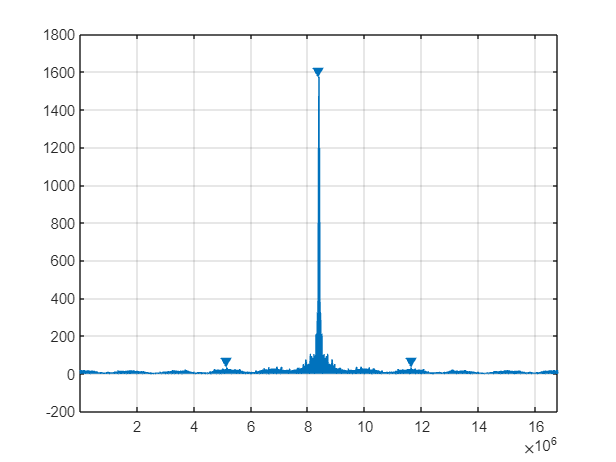


findpeaks(abs(doppler), MinPeakProminence=25, MinPeakDistance=3e6)

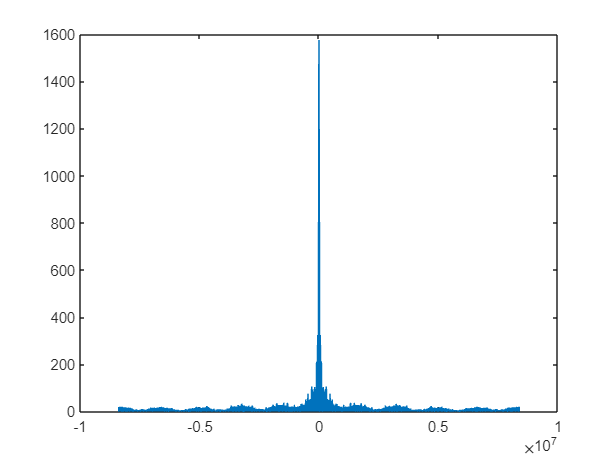


figure();
plot((1:length(doppler)) - round(length(doppler) / 2), abs(doppler));


if (processingType == 4)||(processingType == 5)
    NrFrmsInkHz = frequencykHz(1+NrFrms)-frequencykHz(1);
    
    for mobileProcessingIndex=1:floor(NrFrms/mobileTagLocalizationInterval)+1
        chirpIndex = 1+(mobileProcessingIndex-1)*mobileTagLocalizationInterval;
        
        totalPaddedFreqData = zeros(N*(numZeroPads),numTags);
        totalPaddedFreq = zeros(N*(numZeroPads),numTags);
        for tempTagIndex = 1:numTags
            ifftData = ifft(tagDataComplexMobile(:,tempTagIndex));
            
            zeroPaddedData = zeros(1,N*(numZeroPads));
            zeroPaddedData(1:N) = ifftData((chirpIndex-1)*N+1:chirpIndex*N);
            
            paddedFreqData = fft(zeroPaddedData);
            
            paddedFreqIndex = ((1:length(paddedFreqData))-round(length(paddedFreqData)/2)).';
            paddedFreqHz = paddedFreqIndex/length(paddedFreqIndex)*fs;
            paddedFreqkHz = paddedFreqHz/1000;
            
            totalPaddedFreqData(:,tempTagIndex) = abs(paddedFreqData);
            totalPaddedFreq(:,tempTagIndex) = paddedFreqkHz;

## Find the radar-tag range.

            paddedFreqDataCut = zeros(length(paddedFreqData),1);
            
            freqLowerBound = interp1(paddedFreqkHz,1:length(paddedFreqkHz),(150-maxFrequencyRange-10),'nearest');
            freqHigherBound = interp1(paddedFreqkHz,1:length(paddedFreqkHz),(150+maxFrequencyRange+10),'nearest');
            paddedFreqDataCut(freqLowerBound:freqHigherBound) = paddedFreqData(freqLowerBound:freqHigherBound);
            
            [a,b,c] = findpeaks(abs(paddedFreqDataCut)./1e4,paddedFreqkHz);
            
            peakValues = zeros(1,2);
            peakIndexs = zeros(1,2);
            for tempIndex = 1:2
                [value, impulse] = max(a);
                a(impulse) = 0;
                peakValues(1,tempIndex) = value;
                peakIndexs(1,tempIndex) = impulse;
            end
            
            sortedPeakIndex = sort(peakIndexs);
            
            
            if (b(sortedPeakIndex(2))-b(sortedPeakIndex(1))) < 1.5*NrFrmsInkHz
                [value, impulse] = max(peakValues);
                peakFreq1 = b(peakIndexs(impulse));
                peakFreq2 = peakFreq1;
            else
                peakFreq1 = b(sortedPeakIndex(1));
                peakFreq2 = b(sortedPeakIndex(2));
            end
            
            freqDistance = abs(peakFreq1-peakFreq2)/2*1000;
            
            lightSpeed = physconst('LightSpeed');
            
            distanceResult = freqDistance*lightSpeed*(N-1)/(2*1e6*250*1e6) - tagOffset;
            disp(freqDistance)
            
            if plotProcess > 0
                figure()
                plot(totalPaddedFreq(:,tempTagIndex),totalPaddedFreqData(:,tempTagIndex));
                title('Hawkeye Result')
                xlabel('Frequency (kHz)')
                ylabel('Amplitude') 
            end

## Save peak amplitude.

            refPeakSample = min(interp1(paddedFreqkHz,1:length(paddedFreqkHz), peakFreq1,'nearest'), interp1(paddedFreqkHz,1:length(paddedFreqkHz), peakFreq2,'nearest'));
            farPeakSample = max(interp1(paddedFreqkHz,1:length(paddedFreqkHz), peakFreq1,'nearest'), interp1(paddedFreqkHz,1:length(paddedFreqkHz), peakFreq2,'nearest'));
            freqPeakMean = (totalPaddedFreqData(refPeakSample,tempTagIndex)+totalPaddedFreqData(farPeakSample,tempTagIndex))/2;

## Apply advancedSR. Find exact radar-tag range by the recovered sinc function.

            if processingType == 5
                
                if peakFreq2 < peakFreq1
                    [peakFreq2, peakFreq1] = deal(peakFreq1,peakFreq2);
                end
                
                
                freqUnit = totalPaddedFreq(2,tempTagIndex)-totalPaddedFreq(1,tempTagIndex);
                shiftedPoint1 = peakFreq1;
                shiftedPoint2 = peakFreq2;
                
                peak1Index = find(totalPaddedFreq(:,tempTagIndex)==peakFreq1);
                peak2Index = find(totalPaddedFreq(:,tempTagIndex)==peakFreq2);
                sweepUnit = 2;
                sweepEnd= 50;
                sincSweepRange=-sweepEnd*freqUnit:sweepUnit*freqUnit:sweepEnd*freqUnit;
                
                minIndex = 0;
                minRMS = inf;
                sincsFinal = 0;
                
                cnt = 0;
                
                for tempIndex = sincSweepRange
                    cnt = cnt+1;
                    shiftedPoint1 = peakFreq1+tempIndex;
                    shiftedPoint2 = peakFreq2-tempIndex;
                    sincs = abs(sincMakePhase(N,numZeroPads, totalPaddedFreq(:,tempTagIndex),shiftedPoint1, shiftedPoint2));
                    sincs = (freqPeakMean/max(sincs))*sincs;
                    
                    rmsWindow = [peak1Index-numZeroPads*6:peak2Index+numZeroPads*6];
                    
                    sincsCut = totalPaddedFreqData(rmsWindow,tempTagIndex)-sincs(rmsWindow);
                    
                    rmsValue = rms(sincsCut);
                    
                    if rmsValue < minRMS
                        minIndex = cnt;
                        minRMS = rmsValue;
                        sincsFinal = sincs;
                    end
                end
                
                newPeakFreq1 = peakFreq1+sincSweepRange(minIndex);
                newPeakFreq2 = peakFreq2-sincSweepRange(minIndex);
                
                freqDistance = abs(newPeakFreq1-newPeakFreq2)/2*1000;
                
                advancedDistanceResult = freqDistance*lightSpeed*(N-1)/(2*1e6*250*1e6) - tagOffset
                
                
                if plotProcess > 0
                    figure()
                    plot(totalPaddedFreq(:,tempTagIndex),totalPaddedFreqData(:,tempTagIndex));
                    hold on
                    plot(totalPaddedFreq(:,tempTagIndex),sincsFinal)
                    title('Hawkeye Result')
                    xlabel('Frequency (kHz)')
                    ylabel('Amplitude')
                    hold off
                    drawnow;
                    
                end
            end
        end
    end
end

if (processingType == 1) || (processingType == 2)
    for tempTagIndex = 1:numTags
        peakValues = zeros(1,3);
        peakIndexs = zeros(1,3);
        tempFreqResultFinal = tagData(:,tempTagIndex);
        for tempIndex = 1:3
            [value, impulse] = max(tempFreqResultFinal(freqLowerBound:freqHigherBound));
            impulse = impulse + freqLowerBound - 1;
            tempFreqResultFinal(impulse-peakBWDown : impulse+peakBWDown) = 0;
            peakValues(1,tempIndex) = value;
            peakIndexs(1,tempIndex) = impulse;
        end
        
        
    end

## Zero-pad the tag signal.

    sampledFreqResult = zeros(tagIndexes(1,numTags),numTags);
    sampledFreqkHz = zeros(tagIndexes(1,numTags),numTags);
    for tempTagIndex = 1:numTags
        if tagIndexes(1,tempTagIndex) ~= round((tagIndexes(3,tempTagIndex)-tagIndexes(2,tempTagIndex))/NrFrms)+1
            disp("Somethings wrong - padding check")
        end
        cnt = 0;
        for j = tagIndexes(2,tempTagIndex):NrFrms:tagIndexes(3,tempTagIndex)
            cnt = cnt+1;
            sampledFreqResult(cnt,tempTagIndex)=tagDataComplex(round(j),tempTagIndex);
            sampledFreqkHz(cnt,tempTagIndex) = frequencykHz(round(j));
        end
    end
    
    totalPaddedFreqData = zeros((numZeroPads)*length(sampledFreqResult),numTags);
    totalPaddedFreq = zeros((numZeroPads)*length(sampledFreqResult),numTags);
    for tempTagIndex = 1:numTags
        ifftData = ifft(sampledFreqResult(:,tempTagIndex));
        
        zeroPaddedData = zeros(1,N*(numZeroPads));
        zeroPaddedData(1:N) = ifftData;
        
        paddedFreqData = fft(zeroPaddedData);
        
        
        paddedFreqIndex=((1:length(paddedFreqData))-round(length(paddedFreqData)/2)).';
        paddedFreqHz=paddedFreqIndex/length(paddedFreqIndex)*fs;
        paddedFreqkHz=paddedFreqHz/1000;
        
        
        offsetToSampleFreq = paddedFreqkHz(1)-sampledFreqkHz(1,tempTagIndex);
        paddedFreqkHz = paddedFreqkHz-offsetToSampleFreq;
        
        [maxImpulseValue, maxImpulseIndex] = max(tagData(:,tempTagIndex));
        maxImpulseFreq = frequencykHz(maxImpulseIndex);

## Calibrate freq. offset (only for plotting purposes).

        candidates = find(round(abs(paddedFreqData),6)==round(maxImpulseValue,6));
        if length(candidates) == 0
            candidates = find(round(abs(paddedFreqData),5)==round(maxImpulseValue,5));
        end
        
        if length(candidates) == 2
            if abs(paddedFreqkHz(candidates(1)) - maxImpulseFreq) > abs(paddedFreqkHz(candidates(2)) - maxImpulseFreq)
                candidates(1) = candidates(2);
            end
        end
        
        offsetToKHzFreq = paddedFreqkHz(candidates(1)) - maxImpulseFreq;
        paddedFreqkHz = paddedFreqkHz-offsetToKHzFreq;
        
        totalPaddedFreqData(:,tempTagIndex) = abs(paddedFreqData);
        totalPaddedFreq(:,tempTagIndex) = paddedFreqkHz;

## Find radar-tag range.

        paddedFreqDataCut = zeros(length(paddedFreqData),1);
        
        freqLowerBound = interp1(paddedFreqkHz,1:length(paddedFreqkHz),(150-maxFrequencyRange-10),'nearest');
        freqHigherBound = interp1(paddedFreqkHz,1:length(paddedFreqkHz),(150+maxFrequencyRange+10),'nearest');
        paddedFreqDataCut(freqLowerBound:freqHigherBound) = paddedFreqData(freqLowerBound:freqHigherBound);
        
        [a,b,c] = findpeaks(abs(paddedFreqDataCut)./1e4,paddedFreqkHz);
        
        peakValues = zeros(1,2);
        peakIndexs = zeros(1,2);
        for tempIndex = 1:2
            [value, impulse] = max(a);
            a(impulse) = 0;
            peakValues(1,tempIndex) = value;
            peakIndexs(1,tempIndex) = impulse;
        end
        
        sortedPeakIndex = sort(peakIndexs);
        
        NrFrmsInkHz = frequencykHz(1+NrFrms)-frequencykHz(1);
        
        
        if (b(sortedPeakIndex(2))-b(sortedPeakIndex(1))) < 1.5*NrFrmsInkHz
            [nvalue1, impulse] = max(peakValues);
            peakFreq1 = b(peakIndexs(impulse));
            peakFreq2 = peakFreq1;
        else
            peakFreq1 = b(sortedPeakIndex(1));
            peakFreq2 = b(sortedPeakIndex(2));
        end
        
        
        freqDistance = abs(peakFreq1-peakFreq2)/2*1000;
        
        lightSpeed = physconst('LightSpeed');
        
        distanceResult = freqDistance*lightSpeed*(tagIndexes(1,numTags)-1)/(2*1e6*250*1e6) - tagOffset

distanceResult = -0.1730

## Save the peak amplitude.

        refPeakSample = min(interp1(paddedFreqkHz,1:length(paddedFreqkHz), peakFreq1,'nearest'), interp1(paddedFreqkHz,1:length(paddedFreqkHz), peakFreq2,'nearest'));
        farPeakSample = max(interp1(paddedFreqkHz,1:length(paddedFreqkHz), peakFreq1,'nearest'), interp1(paddedFreqkHz,1:length(paddedFreqkHz), peakFreq2,'nearest'));
        freqPeakMean = (totalPaddedFreqData(refPeakSample,tempTagIndex)+totalPaddedFreqData(farPeakSample,tempTagIndex))/2;
        
        if processingType == 1
            
            if plotProcess > 0
                figure()
                plot(frequencykHz,tagData(:,tempTagIndex),'k','LineWidth',1)
                hold on
                plot(totalPaddedFreq(:,tempTagIndex),totalPaddedFreqData(:,tempTagIndex));
                title('Hawkeye Result')
                xlabel('Frequency (kHz)')
                ylabel('Amplitude')
                hold off
            end
            
        end

## Apply advancedSR. Find exact radar-tag range by the recovered sinc function.

        if processingType == 2
            
            if peakFreq2 < peakFreq1
                [peakFreq2, peakFreq1] = deal(peakFreq1,peakFreq2);
            end
            
            
            offsetToSampleFreq = totalPaddedFreq(2,tempTagIndex)-totalPaddedFreq(1,tempTagIndex);
            shiftedPoint1 = peakFreq1;
            shiftedPoint2 = peakFreq2;
            
            peak1Index = find(totalPaddedFreq(:,tempTagIndex)==peakFreq1);
            peak2Index = find(totalPaddedFreq(:,tempTagIndex)==peakFreq2);
            sweepUnit = 2;
            sweepEnd= 50;
            sincSweepRange=-sweepEnd*offsetToSampleFreq:sweepUnit*offsetToSampleFreq:sweepEnd*offsetToSampleFreq;
            
            minIndex = 0;
            minRMS = inf;
            sincsFinal = 0;
            
            cnt = 0;
            
            for tempIndex = sincSweepRange
                cnt = cnt+1;
                shiftedPoint1 = peakFreq1+tempIndex;
                shiftedPoint2 = peakFreq2-tempIndex;
                sincs = abs(sincMakePhase(length(sampledFreqResult),numZeroPads, totalPaddedFreq(:,tempTagIndex),shiftedPoint1, shiftedPoint2));
                sincs = (freqPeakMean/max(sincs))*sincs;
                
                rmsWindow = [peak1Index-numZeroPads*6:peak2Index+numZeroPads*6];
                
                sincsCut = totalPaddedFreqData(rmsWindow,tempTagIndex)-sincs(rmsWindow);
                
                rmsValue = rms(sincsCut);
                
                if rmsValue < minRMS
                    minIndex = cnt;
                    minRMS = rmsValue;
                    sincsFinal = sincs;
                end
            end
            newPeakFreq1 = peakFreq1+sincSweepRange(minIndex);
            newPeakFreq2 = peakFreq2-sincSweepRange(minIndex);
            
            freqDistance = abs(newPeakFreq1-newPeakFreq2)/2*1000;
            
            advancedDistanceResult = freqDistance*lightSpeed*(tagIndexes(1,numTags)-1)/(2*1e6*250*1e6) - tagOffset
            
            
            if plotProcess > 0
                figure()
                plot(frequencykHz,tagData(:,tempTagIndex),'k','LineWidth',1)
                hold on
                plot(totalPaddedFreq(:,tempTagIndex),totalPaddedFreqData(:,tempTagIndex));
                plot(totalPaddedFreq(:,tempTagIndex),sincsFinal)
                title('Hawkeye Result')
                xlabel('Frequency (kHz)')
                ylabel('Amplitude')
                hold off
                drawnow;
                
            end
        end
    end
end